# Synthetic HySICS spectra: the updated driver (ver2) and a check against the original

This live script explains how the ver2 synthetic-spectrum driver differs from the original per-band driver, and shows that both produce the same HySICS reflectance spectra for three test clouds.

Files

- Original driver: `Neural_Network/hysics_refl_from_synthetic_NN_inputs.m`

- Updated driver: `Neural_Network/hysics_refl_from_synthetic_NN_inputs_ver2.m`

- Chunk runner (parallel over clouds, one output file): `Neural_Network/run_synthetic_spectra_chunk.m`

- Spectral response functions: `HySICS/create_HySICS_specResponse_ver2.m`

- Data shown here: `Testing/driver_ver1_vs_ver2_comparison_14Nov2026.mat`

The comparison was run on the laptop (MATLAB R2024b, libRadtran 2.0.6) on 14 Nov 2026 for clouds 553, 27045 and 21014 of `training_inputs_jointMVN_N100000_L7_2026-11-12.nc`. Both drivers used the same libRadtran settings (DISORT, 16 streams, REPTRAN coarse, custom Mie tables, mixed-layer water-cloud files) and the same 6-nm-FWHM response functions.

% Load the comparison data saved next to this live script. The folder is
% found by trying, in order: this script's folder, the folder the live script
% is found in on the MATLAB path, the current folder, and the Testing folder
% of the laptop repository. The figure PNG is written to the same folder.
data_name = 'driver_ver1_vs_ver2_comparison_14Nov2026.mat';
candidates = {fileparts(mfilename('fullpath')), ...
    fileparts(which('compare_synthetic_driver_ver1_ver2')), pwd, ...
    '/Users/andrewbuggee/Documents/MATLAB/Matlab-Research/Hyperspectral_Cloud_Retrievals/Testing'};
here = '';
for c = 1:numel(candidates)
    if ~isempty(candidates{c}) && isfile(fullfile(candidates{c}, data_name))
        here = candidates{c};
        break
    end
end
if isempty(here)
    error('Could not find %s; put it next to this live script.', data_name);
end
D = load(fullfile(here, data_name));

wl_nm   = D.band_center_wavelength_nm(:);     % (636 x 1) nm, Gaussian centre of each band
win_nm  = D.band_window_nm;                   % (636 x 2) nm, response window of each band
ids     = D.cloud_idx(:)';                    % cloud indices (rows of the .nc)
R_old   = D.R_old;                            % (3 x 636) reflectance, original driver
R_new   = D.R_new;                            % (3 x 636) reflectance, ver2 driver

## 1. Why the original driver repeats work

The original driver runs libRadtran's `uvspec` once for every HySICS band: 636 runs per cloud. Each run covers that band's response window, a 40-nm stretch of spectrum centred on the band. HySICS bands are only about 3 nm apart, so each window overlaps about a dozen of its neighbours, and every wavelength in the spectrum is computed again for every band whose window contains it.

The cell below measures this from the response functions themselves.

window_width_nm = win_nm(:, 2) - win_nm(:, 1);      % nm, width of each band's window
band_spacing_nm = diff(wl_nm);                      % nm, distance between band centres

% Overlap factor: total wavelength range computed by the 636 separate runs,
% divided by the range the spectrum actually spans.
overlap_factor = sum(window_width_nm) / (max(win_nm(:, 2)) - min(win_nm(:, 1)));

fprintf('Response window per band : %.1f nm\n', median(window_width_nm));

Response window per band : 39.9 nm


fprintf('Spacing between bands    : %.2f nm\n', median(band_spacing_nm));

Spacing between bands    : 3.06 nm


fprintf('Overlap factor           : %.1f (each wavelength computed this many times)\n', overlap_factor);

Overlap factor           : 12.8 (each wavelength computed this many times)


## 2. What the ver2 driver does instead

The ver2 driver splits the 636 bands into four contiguous groups and runs `uvspec` once per group, over the union of that group's response windows. Each band's reflectance is then taken from its own window of that output, using the same function as before, `reflectanceFunction_ver3`:


$$R_b = \frac{\int R(\lambda)\, S_b(\lambda)\, F_0(\lambda)\, d\lambda}{\int S_b(\lambda)\, F_0(\lambda)\, d\lambda}, \qquad R(\lambda) = \frac{\pi\, I(\lambda)}{\mu_0\, F_0(\lambda)}$$


where I is the top-of-atmosphere radiance from libRadtran, F0 the solar irradiance, mu0 the cosine of the solar zenith angle and S_b the response function of band b. Only how many times `uvspec` is called changes; the formula is the same as in the original driver.

Why the result does not change: libRadtran's REPTRAN gas-absorption scheme computes radiances at a fixed set of representative wavelengths for each of its spectral bands (Gasteiger et al., 2014). It follows (an inference, not stated in the REPTRAN paper, and confirmed by the comparison below) that the radiance at a given wavelength therefore does not depend on how wide a range one `uvspec` run covers, so cutting a band's window out of a long run gives the same numbers as a run over that window alone.

Why four groups rather than one run over the whole spectrum: one run over 332-2317 nm peaked at 5.0 GB of memory, above the 3.8 GB per core of CURC's Alpine cluster. The largest of the four group runs (332-856 nm) peaked at 3.1 GB. Both were measured on the laptop with /usr/bin/time.

seg = D.segment_ranges_nm;
fprintf('uvspec runs per cloud: original 636, ver2 %d\n', size(seg, 1));

uvspec runs per cloud: original 636, ver2 4


for s = 1:size(seg, 1)
    fprintf('  group %d: %7.1f - %7.1f nm\n', s, seg(s, 1), seg(s, 2));
end

  group 1:   332.0 -   855.9 nm
  group 2:   819.0 -  1342.9 nm
  group 3:  1306.1 -  1830.0 nm
  group 4:  1793.1 -  2317.0 nm


fprintf('Peak memory of one uvspec run: full range %.1f GB, largest group %.2f GB\n', ...
    D.peak_mem_full_range_GB, D.peak_mem_segment1_GB);

Peak memory of one uvspec run: full range 5.0 GB, largest group 3.15 GB


## 3. Other changes that come with ver2

- Parallel over clouds, not over bands. `run_synthetic_spectra_chunk.m` gives each MATLAB worker whole clouds (`parfor` over clouds), so a 32-CPU Alpine task computes 32 clouds at once.

- One output file per Slurm task instead of one per cloud. Each original file took 2.6 MB on disk, most of it a copy of the 636 x 401 response-function table (4.1 MB uncompressed) that is the same for every cloud; the ver2 chunk file stores a clouds-by-636 reflectance matrix plus each cloud's inputs. It is rewritten after every block of clouds, so a task that reaches its time limit keeps the clouds it finished and a resubmitted task resumes from that file.

- No noise is added in MATLAB. The original added unseeded Gaussian noise that the HDF5 converters never used; the converters add seeded noise to the clean reflectance (RANDOM_SEED = 20261114).

- Response functions from `create_HySICS_specResponse_ver2.m`: a fixed 6-nm FWHM for every band (P. Pilewskie, 13 Oct 2026), without reading 'ILS Map.txt'. They are computed once per chunk and are identical to the committed  `create_HySICS_specResponse.m`.

- Each cloud deletes only its own INP, OUT, water-cloud and radiosonde files. The original deleted every such file in the shared folders, which would remove other clouds' files when clouds run concurrently.

## 4. Check: reflectance spectra from both drivers

One panel per cloud. The original driver is the thick blue line; the ver2 driver is drawn on top as a thin dashed orange line. Where the two agree, the orange line runs along the centre of the blue one.

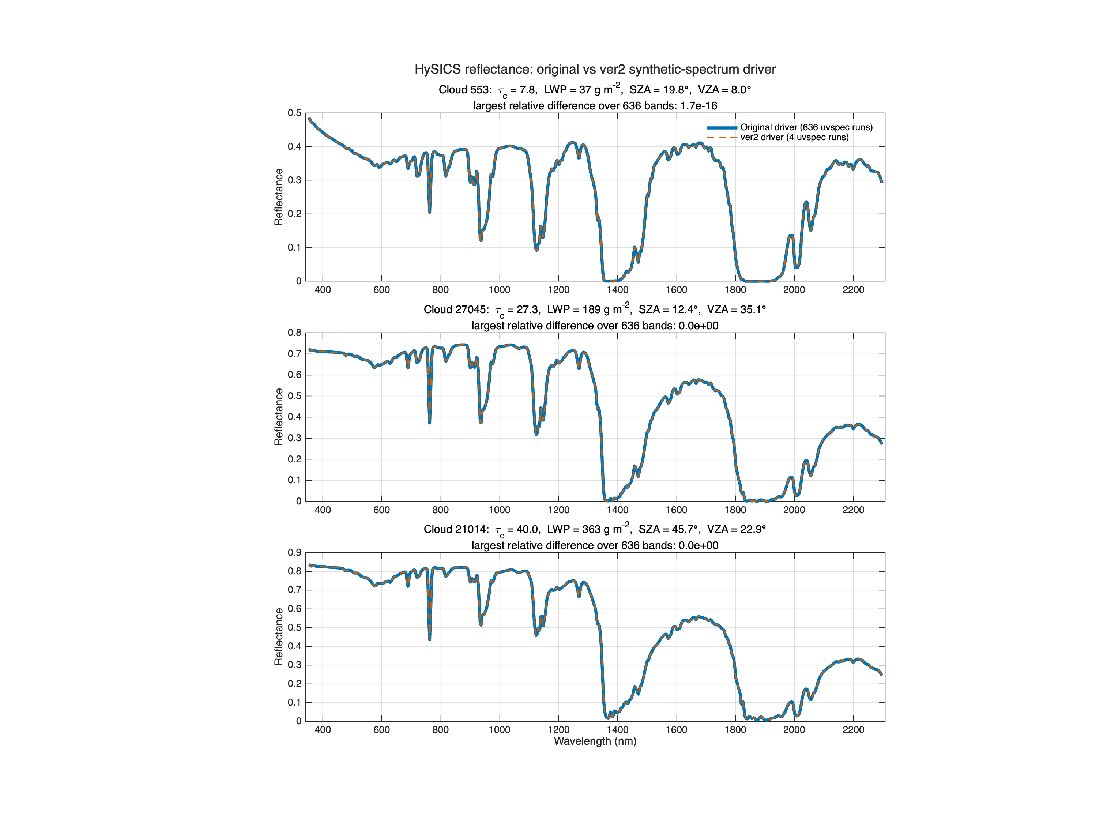

c_old = [0 114 178] / 255;      % Okabe-Ito blue
c_new = [213 94 0]  / 255;      % Okabe-Ito vermillion

% The figure is drawn invisibly with MATLAB's factory graphics defaults
% (new_figure, below) and saved as a PNG, which is then displayed. startup.m
% sets dark root defaults, and exporting visible figures can stall R2024b.
fig = new_figure('Visible', 'off', 'Units', 'inches', 'Position', [1 1 9 9.5]);
tl = tiledlayout(fig, 3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

for k = 1:numel(ids)
    ax = nexttile(tl);
    plot(ax, wl_nm, R_old(k, :), '-', 'Color', c_old, 'LineWidth', 3, ...
        'DisplayName', 'Original driver (636 uvspec runs)');
    hold(ax, 'on');
    plot(ax, wl_nm, R_new(k, :), '--', 'Color', c_new, 'LineWidth', 1.2, ...
        'DisplayName', 'ver2 driver (4 uvspec runs)');
    hold(ax, 'off');
    grid(ax, 'on');
    xlim(ax, [min(wl_nm) - 10, max(wl_nm) + 10]);
    ylabel(ax, 'Reflectance');

    % largest relative difference over the 636 bands for this cloud
    rel_diff = max(abs(R_new(k, :) - R_old(k, :)) ./ abs(R_old(k, :)));
    title(ax, {sprintf(['Cloud %d:  \\tau_c = %.1f,  LWP = %.0f g m^{-2},  ' ...
        'SZA = %.1f\\circ,  VZA = %.1f\\circ'], ids(k), D.tau_c(k), ...
        D.LWP_g_per_m2(k), D.sza_deg(k), D.vza_deg(k)), ...
        sprintf('largest relative difference over 636 bands: %.1e', rel_diff)}, ...
        'FontWeight', 'normal');
    if k == 1
        legend(ax, 'Location', 'northeast', 'Box', 'off');
    end
    if k == numel(ids)
        xlabel(ax, 'Wavelength (nm)');
    end
end
title(tl, 'HySICS reflectance: original vs ver2 synthetic-spectrum driver', 'FontSize', 13);

png_file = fullfile(here, 'driver_ver1_vs_ver2_spectra.png');
exportgraphics(fig, png_file, 'Resolution', 200);
close(fig);

figure;
image(imread(png_file));
axis image off

## 5. Differences and run times

The table lists, for each cloud, the largest relative difference between the two drivers over the 636 bands, how many bands differ at all, and the run time of each driver on the laptop. The original driver ran one cloud at a time on 10 MATLAB workers; ver2 ran each cloud on a single worker, three clouds side by side.

max_rel_diff   = max(abs(R_new - R_old) ./ abs(R_old), [], 2);   % (3 x 1)
n_bands_differ = sum(R_new ~= R_old, 2);                         % (3 x 1)
t_old_core_s   = D.t_old_wall_s(:) * D.n_workers_old;            % s, wall time x workers
t_new_core_s   = D.t_new_cloud_s(:);                             % s, one worker per cloud

T = table(ids(:), max_rel_diff, n_bands_differ, D.t_old_wall_s(:), t_old_core_s, t_new_core_s, ...
    'VariableNames', {'cloud', 'max_rel_diff', 'bands_differing', ...
    'old_wall_s_10workers', 'old_worker_s', 'new_worker_s'});
disp(T)

    cloud    max_rel_diff    bands_differing    old_wall_s_10workers    old_worker_s    new_worker_s
    _____    ____________    _______________    ____________________    ____________    ____________

      553     1.7023e-16            1                  415.1                4151           155.05   
    27045              0            0                  392.3                3923           157.94   
    21014              0            0                  391.1                3911           158.48   



fprintf('Worker-time ratio, original / ver2: %.0f - %.0f x\n', ...
    min(t_old_core_s ./ t_new_core_s), max(t_old_core_s ./ t_new_core_s));

Worker-time ratio, original / ver2: 25 - 27 x


Clouds 27045 and 21014 are bit-for-bit identical. Cloud 553 differs in one of its 636 bands by 1.7e-16, a single floating-point rounding unit, so the two drivers produce the same spectra.

The worker-time ratio (about 25x here) overstates the speed-up somewhat. The laptop's 10 cores are of two kinds, and the original driver kept all 10 busy while ver2 used three. A cleaner measure is the serial benchmark of 13 Nov 2026 on the same laptop: about 2,160 s of computing for 636 per-band runs against 140-190 s for one run over the whole spectrum, an 11-15x reduction, consistent with the overlap factor in Section 1.

## References

Gasteiger, J., Emde, C., Mayer, B., Buras, R., Buehler, S. A., and Lemke, O. (2014). Representative wavelengths absorption parameterization applied to satellite channels and spectral bands. Journal of Quantitative Spectroscopy and Radiative Transfer, 148, 99-115. doi:10.1016/j.jqsrt.2014.06.024

Emde, C., et al. (2016). The libRadtran software package for radiative transfer calculations (version 2.0.1). Geoscientific Model Development, 9, 1647-1672. doi:10.5194/gmd-9-1647-2016

## Local function

function fig = new_figure(varargin)
% NEW_FIGURE  A figure that uses MATLAB's FACTORY graphics defaults, whatever
% startup.m sets: each root default is replaced, on this figure only, by its
% factory value, so every object drawn in it starts from the factory values
% and other figures are unaffected. Copied from
% EPCAPE_KP_AJB/supersaturation/functions/new_figure.m (Oct 2026).
fig = figure(varargin{:});
defs = fieldnames(get(groot, 'default'));
for k = 1:numel(defs)
    name = defs{k};
    if startsWith(name, 'defaultFigure', 'IgnoreCase', true)
        continue
    end
    set(fig, name, get(groot, regexprep(name, '^default', 'factory', 'ignorecase')));
end
fig.Color = 'w';
end